# **GPU Computing**

GPU stands for graphics processing unit. It is a single-chip processor placed directly on the motherboard or on a graphics board. Originally, GPUs were developed for accelerating and rendering graphical images on the computer monitor. By offloading time-consuming graphical calculations to the GPU, the CPU has more time for other tasks. This made the development of computer games with more realistic graphics possible. These days, GPUs are also used for scientific calculations. The GPU allows for massively parallel arrays of integer and floating-point processing. There are typically hundreds of processors per card fully dedicated to high-speed calculations.

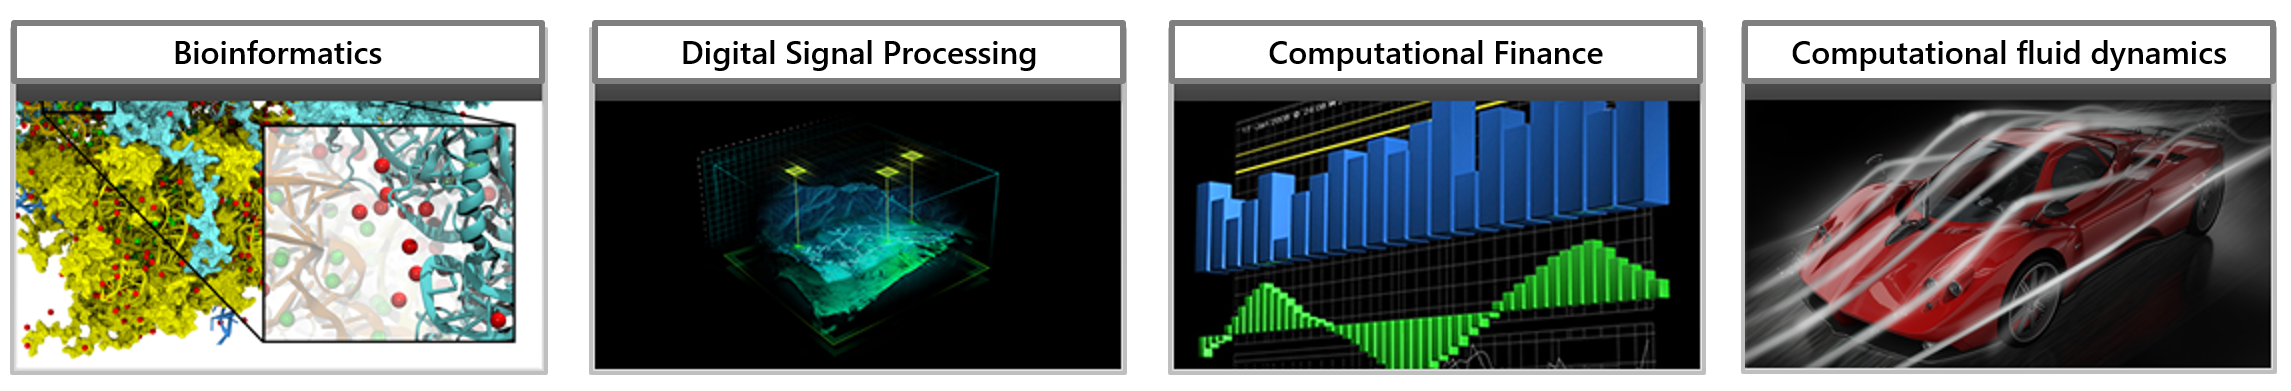

A GPU can accelerate an application if it fits the following criteria: :

- **Massively parallel **—The computations can be broken down into hundreds or thousands of independent units of work.  You will see the best performance when all of the cores are kept busy, exploiting the inherent parallel nature of the GPU. 

- **Computationally intensive **—The time spent on computation significantly exceeds the time spent on transferring data to and from GPU memory. Because a GPU is attached to the host CPU via the PCI Express bus, the memory access is slower than with a traditional CPU. This means that your overall computational speedup is limited by the amount of data transfer that occurs in your algorithm. 

- **Algorithm consists of supported functions **— There is an ever-increasing list of MATLAB built-in functions that support the use of GPUs. Additionally, there are several toolboxes that offer built-in GPU support. Our developers have written CUDA versions of key MATLAB and toolbox functions and presented them as overloaded  functions – We have over 300 GPU-enabled functions in MATLAB and a growing number of GPU-enabled functions in additional toolboxes as well.

The CPU is a versatile and general purpose processor that is optimized for high performance on sequential code. The CPU can run parallel computations on several cores - often two, four, eight, or sometimes even 16. Therefore, there are several considerations when creating parallel code to run on the CPU, such as understanding when code might execute out of order. A GPU can have several hundred smaller cores to perform computations. The high speed of GPUs for some applications is based on different hardware architectures. The GPU was designed to perform highly data parallel tasks with high arithmetic intensity (ratio of arithmetic operations to memory operations). Thus the GPU is optimized to execute the same instructions on many data elements in parallel.

   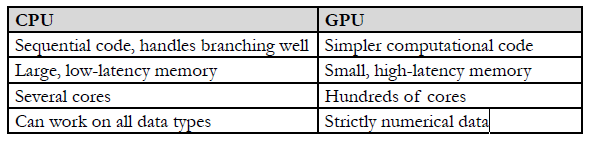                        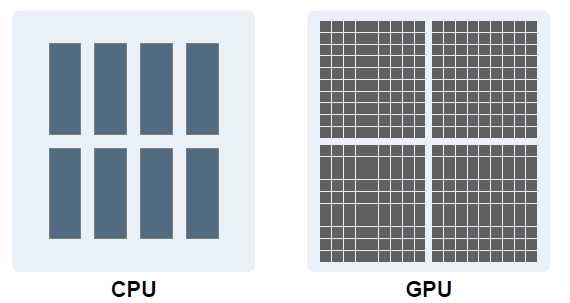

Our tools can both be used to speed up your calculation using multiple CPUs and by using GPUs.  Although GPUs have hundreds of cores, we treat the GPU as a single  unit, and access directly from a  MATLAB computation engine.   For example,  any single Worker can access the entire GPU. Expected speed-up varies with problem specifics as well as the avaialable hardware.

 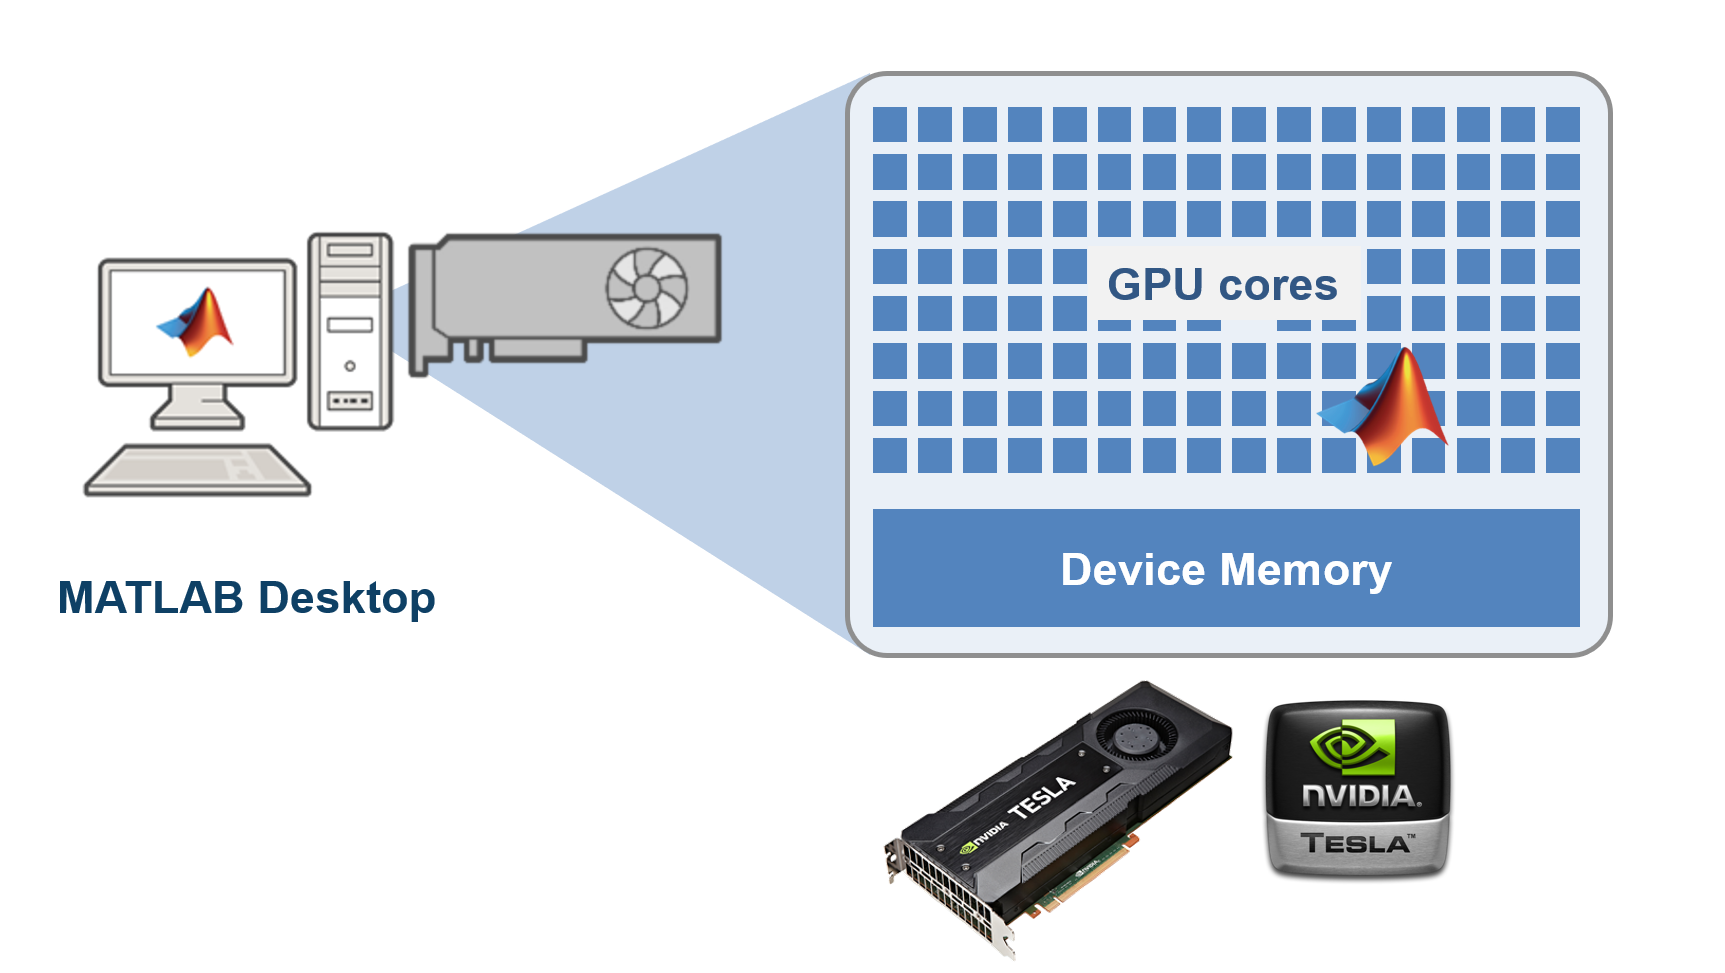

**Available HW resources**

Get information on the CPU (Linux machine)

!uname -a
!lscpu

Get information on the GPU device

d = gpuDevice

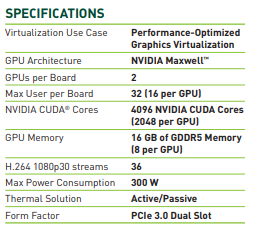[https://images.nvidia.com/content/tesla/pdf/188417-Tesla-M60-DS-A4-fnl-Web.pdf](https://images.nvidia.com/content/tesla/pdf/188417-Tesla-M60-DS-A4-fnl-Web.pdf)

**Programming with GPUs in MATLAB**

The diagram pretty much sums up the easiest way to do GPU computing in MATLAB – Transfer/create data on the GPU using the “gpuArray”, run your function as you would normally - if the inputs are available on the GPU, we do the right thing and run on the GPU and then “gather” the data back to the CPU. This seamless support allows you to run the same code on both the CPU and the GPU.

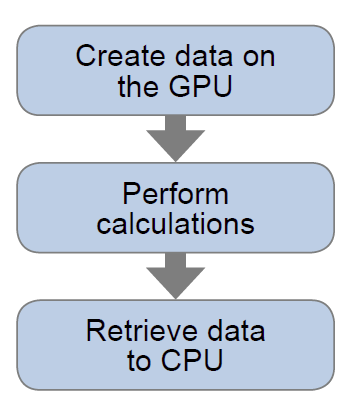

a = rand(4);
A = gpuArray(a);
B = A + 2;
b = gather(B);
whos a A b B

#### Parallel-enabled functions and toolboxes

[https://www.mathworks.com/help/parallel-computing/run-matlab-functions-on-a-gpu.html](https://www.mathworks.com/help/parallel-computing/run-matlab-functions-on-a-gpu.html)

A subset of built-in functions supports the use of gpuArrays. GPU support includes many base MATLAB functions addressing **common teaching disciplines**, like 

- Maths

- Linear algebra

- Descriptive Statistics

- Numerical integration and Differential Equations

- Fourier Analysis and Filtering

GPU execution options are available in:

- MATLAB [Functions with gpuArray support](https://it.mathworks.com/help/matlab/referencelist.html?type=function&capability=gpuarrays)

- Statistics and Machine Learning Toolbox™[Functions with gpuArray support](https://it.mathworks.com/help/stats/referencelist.html?type=function&capability=gpuarrays)

- Image Processing Toolbox™[Functions with gpuArray support](https://it.mathworks.com/help/images/referencelist.html?type=function&capability=gpuarrays)

- Deep Learning Toolbox™ [Functions with gpuArray support](https://it.mathworks.com/help/deeplearning/referencelist.html?type=function&capability=gpuarrays) (see also [Deep Learning with GPUs](https://it.mathworks.com/help/parallel-computing/run-matlab-functions-on-a-gpu.html#mw_9dca79d1-506b-4229-a4d2-3f243b075629))

- Computer Vision Toolbox™[Functions with gpuArray support](https://it.mathworks.com/help/vision/referencelist.html?type=function&capability=gpuarrays)

- Communications Toolbox™[Functions with gpuArray support](https://it.mathworks.com/help/comm/referencelist.html?type=function&capability=gpuarrays)

- Signal Processing Toolbox™[Functions with gpuArray support](https://it.mathworks.com/help/signal/referencelist.html?type=function&capability=gpuarrays)

- Audio Toolbox™[Functions with gpuArray support](https://it.mathworks.com/help/audio/referencelist.html?type=function&capability=gpuarrays)

- Wavelet Toolbox™[Functions with gpuArray support](https://it.mathworks.com/help/wavelet/referencelist.html?type=function&capability=gpuarrays)

- Curve Fitting Toolbox™ [Functions with gpuArray support](https://it.mathworks.com/help/curvefit/referencelist.html?type=function&capability=gpuarrays)

**FFT Example**

CPU = zeros(100,1);
GPU = zeros(100,1);

**Read example image**

I = imread("tumor_091R.tif");

**Compute 100 ffts on CPU**

for i = 1:size(CPU,1)
    tic
    fft(I);
    CPU(i) = toc;
end

**Create gpuArray**

I = gpuArray(I);

**Compute 100 ffts on GPU**

for j = 1:size(GPU,1)
    tic
    fft(I);
    wait(gpuDevice)
    GPU(j) = toc;
end

**Compare average computing time**

avCPU = mean(CPU)
avGPU = mean(GPU)

**Plot results**

disp(['The average iteration runtime for CPU is ' num2str(avCPU)])
disp(['The average iteration runtime for GPU is ' num2str(avGPU)])
percentDifference = avCPU/avGPU;
sprintf('Mean speedup factor of %i',round(percentDifference))
figure
histogram(CPU,10)
hold on
histogram(GPU,10)
legend('CPU','GPU')
set(gca,'TickDir','out','FontSize',18)
box off
xlabel('Iteration time [s]')
ylabel('#Occurences')

### Advanced Programming Constructs

**Using **`arrayfun`**, generating CUDA MEX-Files**

**The Julia Sets**

Julia sets are well known in the area of fractals and complex dynamics. [https://en.wikipedia.org/wiki/Julia_set](https://en.wikipedia.org/wiki/Julia_set)

For this example, consider a quadratic Julia set, generated using the following mapping: $z_{n+1} =z_n^2 +c$, where $z$ is a complex number, and $c$ is a constant.


c = -0.8 + 0.156i;

tic;
% create the complex plane
x = linspace(-1.5,1.5,4000);
y = linspace(-1,1,2000);
[X,Y] = meshgrid(x,y);
Z = complex(X,Y);

% Calculation of the Julia set
for k = 1:100
    Z = Z.^2 + c;
end

% Transformation
Z = exp(-abs(Z));
cpuTime = toc;
disp(['Elapsed time using CPU version: ' num2str(cpuTime) ' seconds.'])
visJulia(x,y,Z)

**The** `arrayfun`** MATLAB function**

For code that cannot be vectorized, the `arrayfun` function allows to perform calculations on each element of the gpuArray

edit juliaCalc.m

c = -0.8 + 0.156i;

tic
% create the complex plane
x = linspace(gpuArray(-1.5),1.5,4000);
y = linspace(gpuArray(-1),1,2000);
[X,Y] = meshgrid(x,y);
Z = complex(X,Y);

% Calculation of the Julia set 
Z = arrayfun(@juliaCalc,Z,c);

% Getting the data back from the GPU
Z = gather(Z);
gpuTime = toc;

disp(['Elapsed time using GPU functions: ' num2str(gpuTime) ' seconds.'])

percentDifference = cpuTime/gpuTime;
sprintf('Mean speedup factor of %f',(percentDifference))

**Generating CUDA® MEX-Files**

Code can be written in the CUDA C and C++ programming language, which allows the programmer control over parallel function execution on an NVIDIA® GPU.

Similarly to generating C code using MATLAB Coder, you can generate CUDA code using the **GPU Coder**. In general, the process is quite similar. This includes an app leading you through the process. It can be started from the Apps tab or by running

A key difference is that you can indicate what portions of the code should be mapped to the GPU by using the `coder.gpu.kernelfun` pragma. For optimal performance, the MATLAB code should contain a for-loop that could be parallelized. In that case, you can also use the `coder.gpu.kernel` pragma instead of `coder.gpu.kernelfun`

In the GPU Coder app, you can specify which variables should reside on the GPU and which ones on the CPU.

You can also generate a MATLAB script to automate the code generation process

edit gpufun2_script.m

Let's now run the MEX file on the GPU

c = -0.8 + 0.156i;

tic
% create the complex plane
x = linspace(gpuArray(-1.5),1.5,4000);
y = linspace(gpuArray(-1),1,2000);
[X,Y] = meshgrid(x,y);
Z = complex(X,Y);

% Calculation of the Julia set 
Z = gpufun2_mex(X,Y, real(c), imag(c));

% Getting the data back from the GPU
Z = gather(Z);
gpuMexTime = toc;

disp(['Elapsed time using CUDA MEX file: ' num2str(gpuMexTime) ' seconds.'])

percentDifference = cpuTime/gpuMexTime;
sprintf('Mean speedup factor of %f',(percentDifference))


**Using Preexisting CUDA® Code**

[https://www.mathworks.com/help/parallel-computing/run-cuda-or-ptx-code-on-gpu.html](https://www.mathworks.com/help/parallel-computing/run-cuda-or-ptx-code-on-gpu.html)

If applications are already written in CUDA, they can be interfaced with MATLAB by either creating and calling the CUDA kernel from MATLAB or by using the CUDA MEX Interface.

**Invoking a CUDA Kernel from MATLAB**

1) Compile CUDA code (.cu) to create a .ptx file. This can be done with the NVCC compiler that is contained in the NVIDIA CUDA toolkit. This needs to be done only the first time or when you change your CUDA code.

2) Create a kernel object from the .cu and .ptx file

3) Specify kernel properties as needed and run the kernel using `feval`. The inputs can be regular numeric arrays or gpuArrays.

4) Retrieve the data from the GPU using `gather`

[gpuCudaTime, Z] = juliaCuda(false);
percentDifference = cpuTime/gpuMexTime;
sprintf('Mean speedup factor of %f',(percentDifference))

**Using the CUDA MEX Interface **

[https://www.mathworks.com/help/parallel-computing/run-mex-functions-containing-cuda-code.html](https://www.mathworks.com/help/parallel-computing/run-mex-functions-containing-cuda-code.html)

A MEX-function is another way in which CUDA code can be interfaced with MATLAB. To create a MEX-file, a specific interface is required. 

Although the interface requires additional coding and troubleshooting, there are two benefits of MEX-functions 

- MEX-files can interact with hostside libraries, such as the NVIDIA Performance Primitives (NPP) or CUFFT libraries, and can also contain calls from the host to functions in the CUDA run-time library

- MEX-files can analyze the size of the input and allocate memory of a different size, or open grids of a different size, from C or C++ code. In comparison, MATLAB code that calls `CUDAKernel` objects must preallocate output memory and determine the grid size

**GPU Computing Summary**

The effort associated with getting the computations onto the GPU varies depending on the method used. There is little effort involved in invoking built-in functions on gpuArrays. MATLAB code may have to be rewritten before generating CUDA code from it. Integrating CUDA code is also more effort than just invoking existing functions, but the programmer also has more control over how the GPU processes the data.

The table to the right compares the execution times of calculating the Julia set using different implementations with an Intel® Xeon® E5-2690 v3 processor and an NVIDIA® Tesla® M60 GPU.

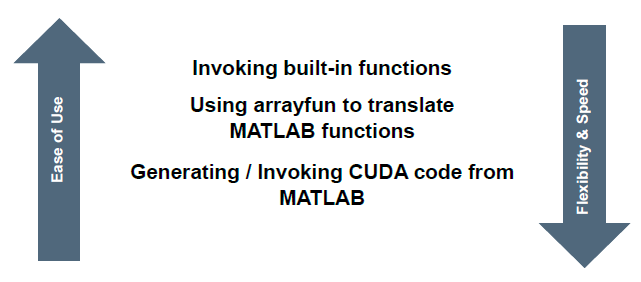                            

### GPU and deep learning

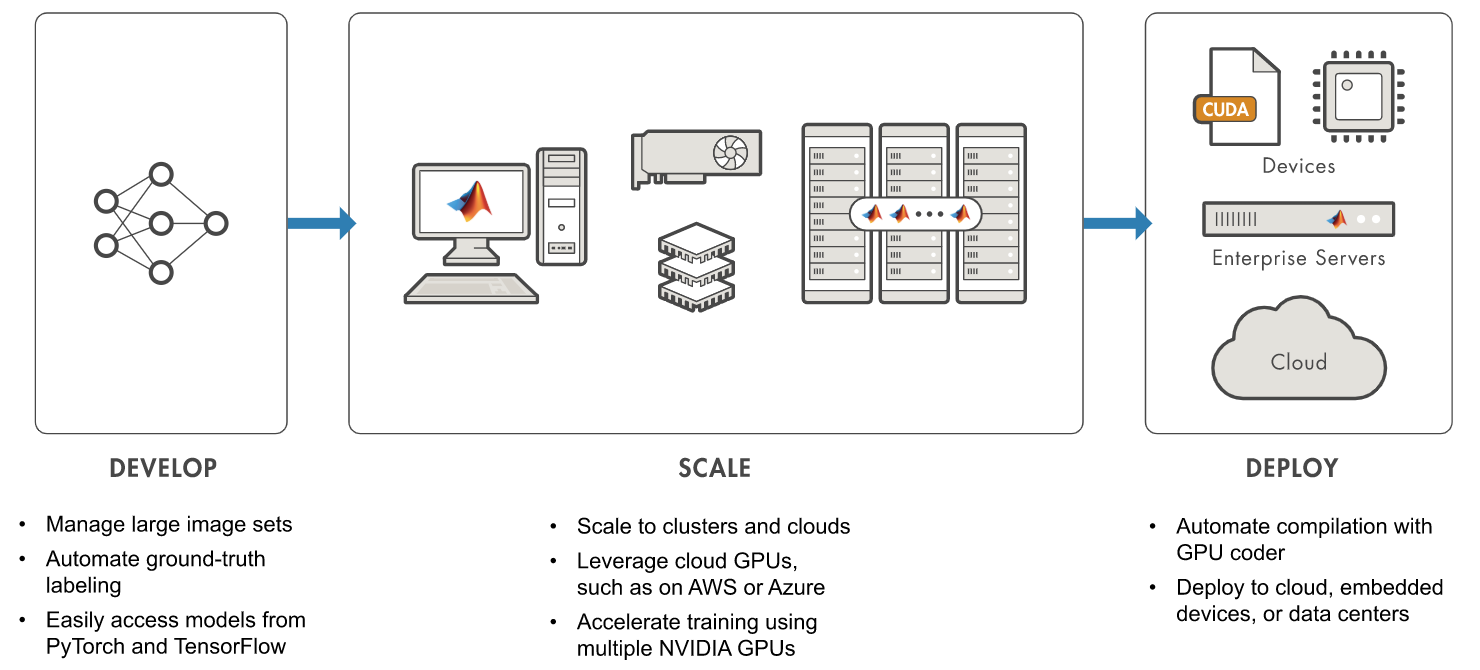

## Conclusion

There are multiple options for speeding up your MATLAB® programs and Simulink® models using you desktop or scaling you applications beyond it. 

Take advantage of your desktop resources using Parallel Computing Toolbox™, and then easily scale your application beyond the desktop to use additional hardware resources without changing your algorithmic code. Our parallel computing tools can support a broad variety of cluster types.   We can support ad-hoc cluster made from workstations, traditional clusters, and even the cloud

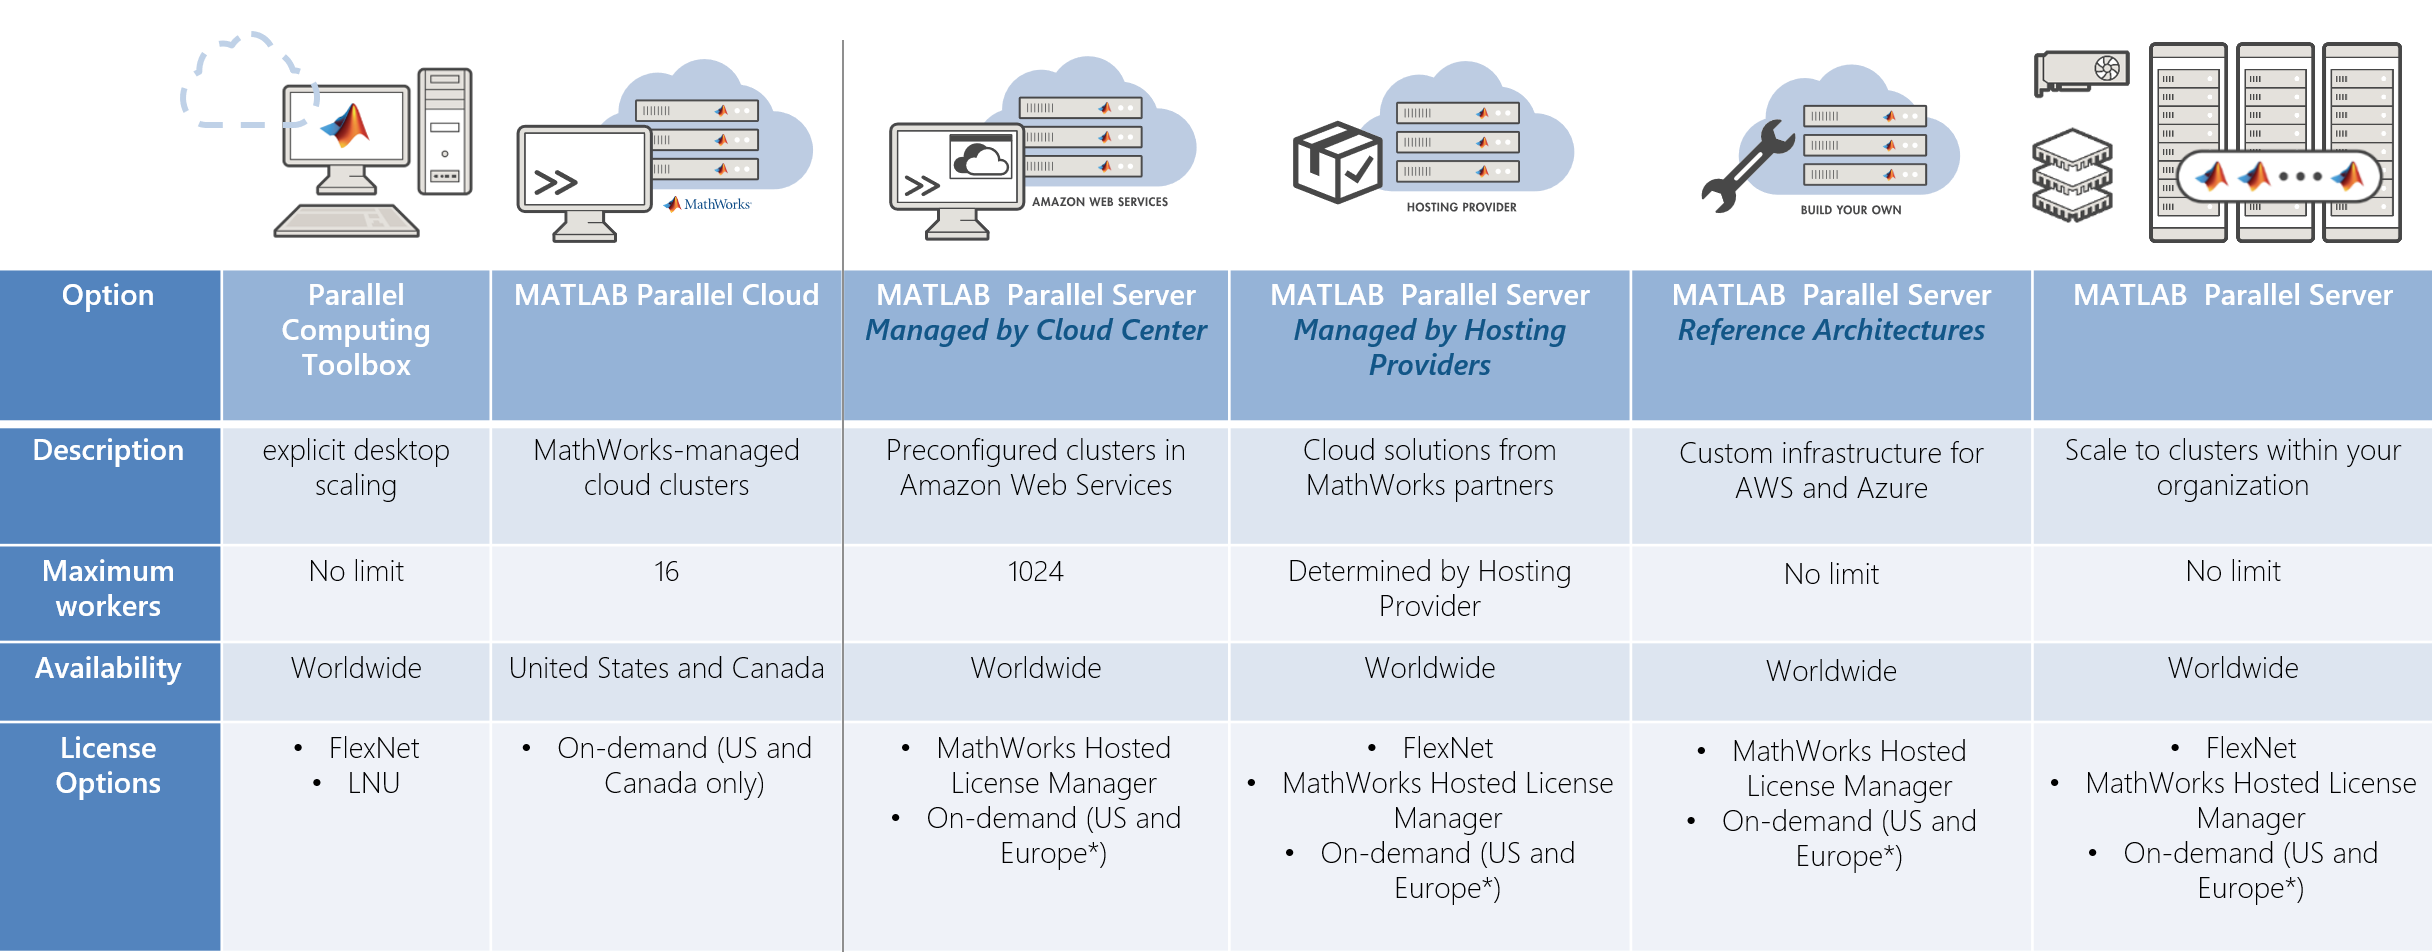

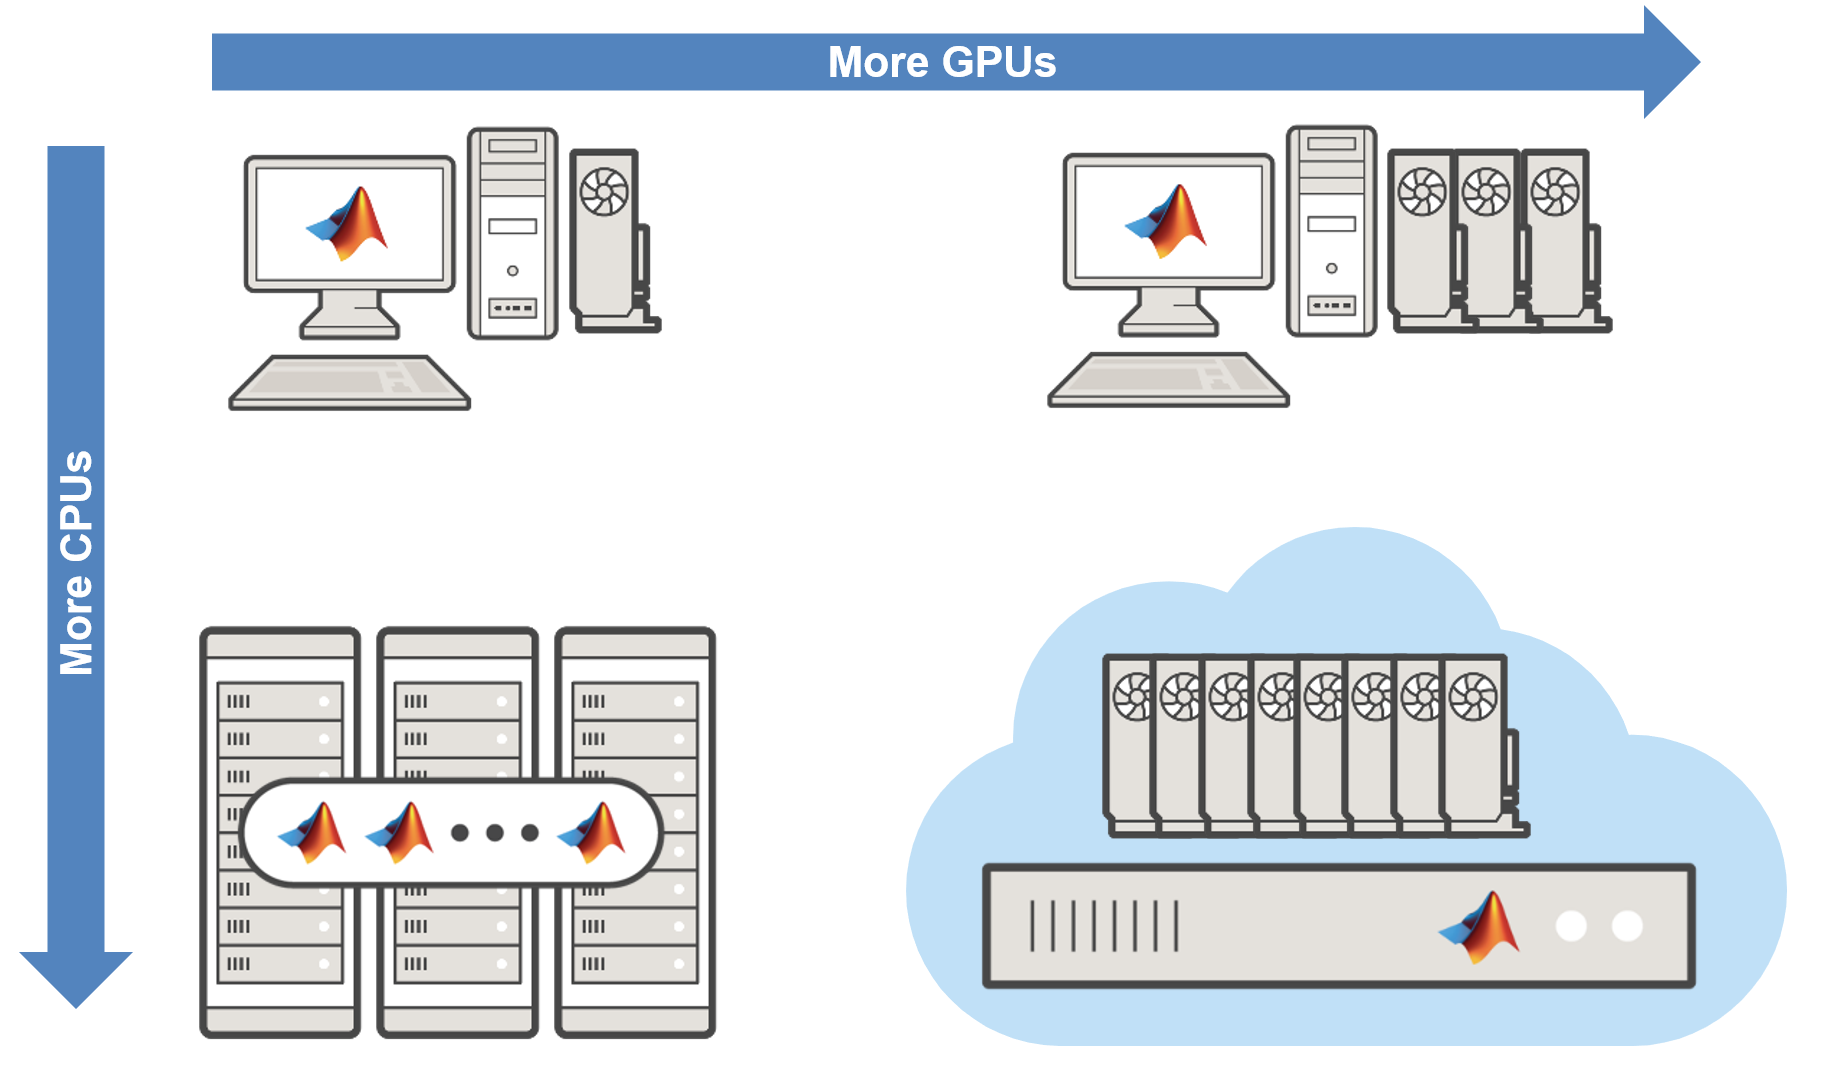

**Need support?**

Installation technical support: [emea-install@mathworks.com](http://emea-install@mathworks.com)    

Technical support: [support@mathworks.com](http://support@mathworks.com)

**Useful resources:**

[https://it.mathworks.com/videos/parallel-computing-toolbox-overview-69513.html](https://it.mathworks.com/videos/parallel-computing-toolbox-overview-69513.html)

MATLAB Documentation

- [MATLAB ](http://www.mathworks.com/help/matlab/performance-and-memory.html)[Advanced Software Development ](http://www.mathworks.com/help/matlab/performance-and-memory.html)[Performance and  Memory](http://www.mathworks.com/help/matlab/performance-and-memory.html)

- [Parallel Computing Toolbox](http://www.mathworks.com/help/distcomp/index.html)

Parallel and GPU Computing Tutorials

- [https://www.mathworks.com/videos/series/parallel-and-gpu-computing-tutorials-97719.html](https://www.mathworks.com/videos/series/parallel-and-gpu-computing-tutorials-97719.html) 

Parallel Computing on the Cloud with MATLAB

- [http://www.mathworks.com/products/parallel-computing/parallel-computing-on-the-cloud/](http://www.mathworks.com/products/parallel-computing/parallel-computing-on-the-cloud/) 

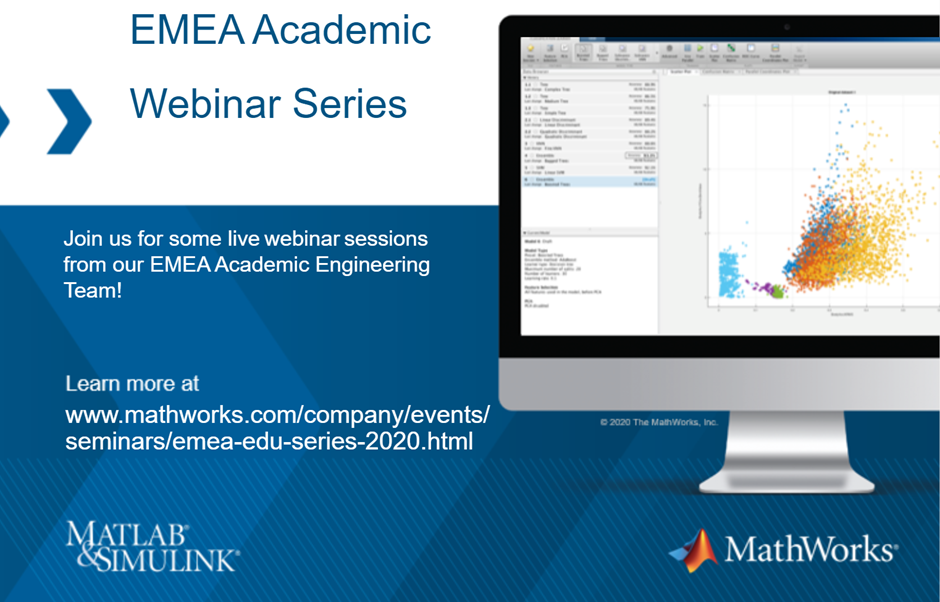

[https://www.mathworks.com/company/events/seminars/emea-edu-series-2020.html](https://www.mathworks.com/company/events/seminars/emea-edu-series-2020.html)